red = [255/255, 107/255, 107/255];
green = [15/255, 185/255, 165/255];
blue = [77/255, 150/255, 255/255];

red_a = [215/255, 77/255, 77/255];
green_a = [5/255, 130/255, 110/255];
blue_a = [47/255, 110/255, 215/255];

label_fontsz=30;
title_fontsz=30;
axis_sz=16;
legends_sz=20;

% Assuming your data is in these variables (each column is a condition, each row is a subject)
group1 = exo_no.DC;  % no_exo
group2 = exo_off.DC; % exo_off
group3 = exo_on.DC;  % exo_on

% Paired t-test between no_exo and exo_off
[h1, p1] = ttest(mean(group1,2), mean(group2,2));
[h2, p2] = ttest(mean(group2,2), mean(group3,2));
[h3, p3] = ttest(mean(group1,2), mean(group3,2));

% Create a table for the p-values
comparison = {'no_exo vs exo_off'; 'exo_off vs exo_on'; 'no_exo vs exo_on'};
p_values = [p1; p2; p3];
results_table = table(comparison, p_values, 'VariableNames', {'Comparison', 'p_value'});

disp('Paired t-test results:');

Paired t-test results:


disp(results_table);

         Comparison           p_value  
    _____________________    __________

    {'no_exo vs exo_off'}    1.2428e-05
    {'exo_off vs exo_on'}       0.54175
    {'no_exo vs exo_on' }     0.0033305




% Optionally, apply Bonferroni correction:
alpha = 0.05 / 3; % Adjusted alpha level for three comparisons
% Determine significance based on the Bonferroni-corrected alpha level
significance = p_values <= alpha;

% Add significance results to the table
results_table.Significance = significance;

% Display the table with significance
disp('Paired t-test results with Bonferroni correction:');

Paired t-test results with Bonferroni correction:


disp(results_table);

         Comparison           p_value      Significance
    _____________________    __________    ____________

    {'no_exo vs exo_off'}    1.2428e-05       true     
    {'exo_off vs exo_on'}       0.54175       false    
    {'no_exo vs exo_on' }     0.0033305       true     




% Display adjusted alpha level for reference
disp(['Bonferroni-corrected alpha level: ', num2str(alpha)]);

Bonferroni-corrected alpha level: 0.016667


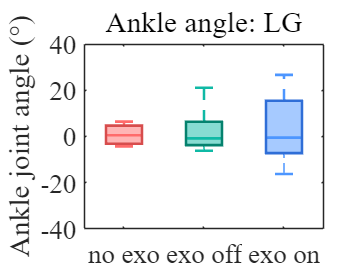

% 데이터 설정
data = [median(group1,2),median(group2,2),median(group3,2)];
labels = {'no exo', 'exo off', 'exo on'};

% 상자 그림 생성
figure;
boxplot(data, 'Labels', labels, 'Whisker', 1.5,'BoxStyle','outline');

% 그래프 설정
ylabel('Ankle joint angle (°)', 'FontSize', label_fontsz); % y축 레이블 폰트 크기 조정
title('Ankle angle: LG', 'FontSize', title_fontsz); % 타이틀 폰트 크기 조정
set(gca, 'FontSize', axis_sz,'FontName','Times New Roman', 'FontSize', 20);
ylim([-40, 40]);


% 스타일 설정 (색상 변경)
h = findobj(gca, 'Tag', 'Box');
colors = [
    blue;    % red for without exo
    green;    % green for exo off
    red     % blue for exo on
];
edge_colors = {blue_a, green_a, red_a}; % 빨강, 초록, 파랑

for j = 1:length(h)
    patch(get(h(j), 'XData'), get(h(j), 'YData'), colors(j,:), 'FaceAlpha', .5,'EdgeColor',edge_colors{j}, 'linewidth',2);
end
% 중간선 색상 변경
median_lines = findobj(gca, 'Tag', 'Median');
median_colors = [
    blue;    % blue for without exo
    green;    % green for exo off
    red     % red for exo on
];
for k = 1:length(median_lines)
    median_lines(k).Color = median_colors(k, :);
    median_lines(k).LineWidth=2;
end

% Custom color for outliers
outliers = findobj(gca, 'Tag', 'Outliers');
outlier_color = [blue',green',red']; % Change this to your desired color

for k = 1:length(outliers)
    outliers(k).MarkerEdgeColor = outlier_color(k,:);
end

% lower shadow, higher shadow 선 색상 변경
lower_whisker = findobj(gca, 'Tag', 'Lower Whisker');
upper_whisker = findobj(gca, 'Tag', 'Upper Whisker');
lower_adjacent = findobj(gca, 'Tag', 'Lower Adjacent Value');
upper_adjacent = findobj(gca, 'Tag', 'Upper Adjacent Value');
for k = 1:length(lower_whisker)
    lower_whisker(k).Color = median_colors(k, :);
    upper_whisker(k).Color = median_colors(k, :);
    lower_adjacent(k).Color = median_colors(k, :);
    upper_adjacent(k).Color = median_colors(k, :);
    lower_adjacent(k).LineWidth=2;
    upper_whisker(k).LineWidth=2;
    lower_adjacent(k).LineWidth=2;
    upper_adjacent(k).LineWidth=2;
end
%overbar(1,2,40,'**');
%overbar(2,3,50,'**');
%overbar(1,3,560,'***');
hold off;

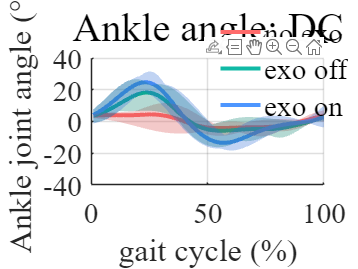

figure;
hold on;

set(gca, 'FontSize', axis_sz,'FontName','Times New Roman', 'FontSize', 22);
plot(mean(group1,2), 'Color', [255/255, 107/255, 107/255], 'LineWidth', 3); %red
plot(mean(group2,2), 'Color',[15/255, 185/255, 165/255], 'LineWidth',3); %green
plot(mean(group3,2), 'Color', [77/255, 150/255, 255/255], 'LineWidth', 3); %blue

plot_shade(group1, [215/255, 77/255, 77/255]); %r
plot_shade(group2, [5/255, 130/255, 110/255]); %g
plot_shade(group3, [47/255, 110/255, 215/255]); %b



xlabel('gait cycle (%)','FontSize', label_fontsz-6);
ylabel('Ankle joint angle (°)','FontSize', label_fontsz-6);
title('Ankle angle: DC','FontSize',30);
legend('no exo','exo off','exo on','Box','off', 'FontSize', 22,"Position", [0.1689,0.69484,0.19286,0.18333]);

grid on
ylim([-40,40]);
hold off;

legend("Position", [0.70015,0.69484,0.19286,0.18333])

legend("Position", [0.67062,0.62059,0.24291,0.24798])

function [hl,ht] = overbar(x1, x2, y, txt)
sz = get(gca,'FontSize');
bg = get(gca,'Color');
d = 2; % size of hook, change depending on y axis scaling
hl = line([x1,x1,x2,x2], [y,y+d,y+d,y],'Color','k');
ht = text((x1+x2)/2, y+d, txt, ...
          'HorizontalAlignment','center', ...
          'VerticalAlignment','middle', ...
          'FontSize',25);
end
function plot_shade(data, color)
    % 데이터의 평균과 최소, 최대 값을 계산
    mean_data = mean(data, 2);
    min_data = min(data, [], 2);
    max_data = max(data, [], 2);
    
    % x축 데이터 정의
    x = 1:length(mean_data);

    % 쉐이딩 플롯
    fill([x fliplr(x)], [min_data' fliplr(max_data')], color, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
end